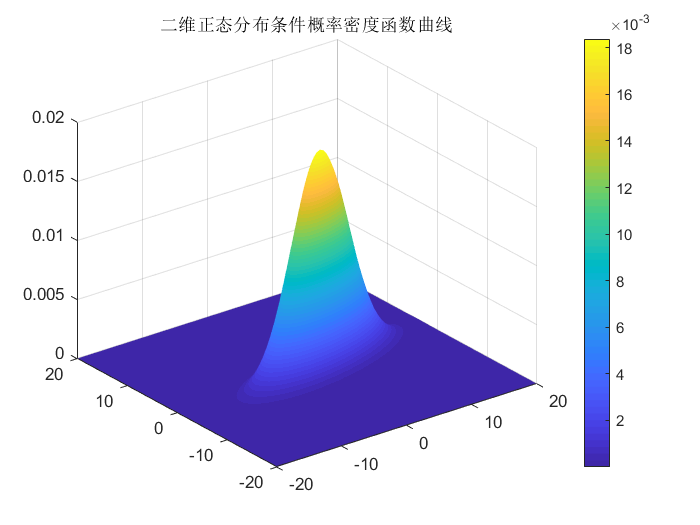

x=-20:0.5:20;
y=-20:0.5:20;
u1 = 2;          %均值
u2 = 0;        
sigma1 = 5;      %方差
sigma2 = 2;
rou = 0.5;     %相关系数
mu=[-1,2];
[X,Y]=meshgrid(x,y); % 产生网格数据并处理
p = 1/(2*pi*sigma1*sigma2*sqrt(1-rou*rou)).*exp(-1/(2*(1-rou^2)).*[(X-u1).*(X-u1)/(sigma1*sigma1)-2*rou*(X-u1).*(Y-u2)/(sigma1*sigma2)+(Y-u2).*(Y-u2)/(sigma2*sigma2)]);
figure(2)
surf(X,Y,p)
shading interp
colorbar
title('二维正态分布条件概率密度函数曲线');